% Data import and categorization.
  A=[78.392199241794643 -0.579331150945265 0.79041165803364488;
   79.83151836782497 -0.048018533489971559 0.18010009224610712;
   80.710204376116678 0.30809874846095936 0.670111336019113;
   78.3702034244389 -0.90205441564363864 -0.035308212492543588;
   78.24548976463204 0.71662669243230259 -0.8811179135382986;
   77.488554464035545 -0.92098346608821513 -0.079327456193004769;
   78.956699726427175 0.28110964844364333 -0.362578948160359;
   80.319616403116044 0.01286908391782191 0.82032089682094234;
   79.8622162318561 0.15423182396449847 0.79572227627626257;
   79.948709274100011 0.75810932755305627 0.302336177225942;
   78.4691219310619 -0.63129310463688459 -0.50789375464803466;
   77.78011775923126 -0.59708532257370739 -0.53195091218474888;
   78.062954561634953 -0.73607909340691291 0.096869989628538627;
   79.967749983001227 0.64441352918909733 -0.21435328192504813;
   80.053887630163842 0.4706860028782387 0.50958956685514634;
   78.689230237648488 0.78697513288073251 -0.21485449977438975;
   77.907496082803846 -0.68063023900594433 -0.4691589237944413;
   79.708922038126758 -0.15541604203464346 -0.30621754997516748;
   80.439471042515123 0.25781546190281263 0.86852528646782612;
   79.983614267828926 0.193562622000573 -0.2522935594332637;
   79.415697134315693 -0.40852106287297829 -0.034947083296464142;
   79.267326116173308 0.56404803602418807 -0.52357079159584141;
   79.814544712511363 -0.23645553145644982 0.062498118206156049;
   79.159856775967754 0.96954238440979734 -0.57975651219318247;
   78.156848236064931 -0.589744040320636 -0.40958587455561429;
   80.687931585891135 0.55950058990826079 0.063971904445298836;
   79.19721058041938 0.69003960356964034 0.015168601787235048;
   79.890267421807025 -0.07742974289683531 -0.0017589860459054306;
   79.870023599434447 0.35825091301744577 0.82299503672555263;
   81.015362306037034 0.5943097614962809 0.46068681535867312;
   78.576980405770556 -0.528850381633194 0.79942436195535149;
   81.78451318703128 0.50445943649227731 0.60984966068057245;
   79.629619400639839 0.84012433644948037 -0.10413159517189001;
   78.581395767256339 0.98927679988604211 -0.52998852489255344;
   79.769410767231022 0.76592614597358732 -0.86575255239919779;
   79.594611240776857 0.006803810614368899 -0.43160248050816108;
   77.462298736129341 -0.9882395857780637 -0.13652414418950798;
   77.755582214325258 -0.96982722888668749 -0.089751314912814448;
   77.13944620238972 -0.808126327936779 0.95870375666078755;
   79.197915310900839 0.57392038322056038 0.85381129024657409;
   79.831219435626025 0.10718518609812974 0.19514747815840111;
   80.278495929997462 0.43903827224890224 0.16735971217449333;
   78.7388892895206 -0.54304303679603549 -0.77385588729752608;
   78.213967934554049 -0.974616204603285 -0.20160058799040712;
   78.165809528742756 -0.75955230079598124 0.88575851500089586;
   80.121041559656533 0.26595649477595484 -0.57135067826325214;
   78.432555674471 -0.96957840279537066 -0.65909523637166667;
   79.8093541908819 0.880531602549604 -0.30623075175428766;
   80.2100797171981 0.99913160433269321 0.24037852020225045;
   79.44873236396802 -0.24356284409497278 -0.12852942985108484];
y=A(:,1);
x1=A(:,2);
x2=A(:,3);

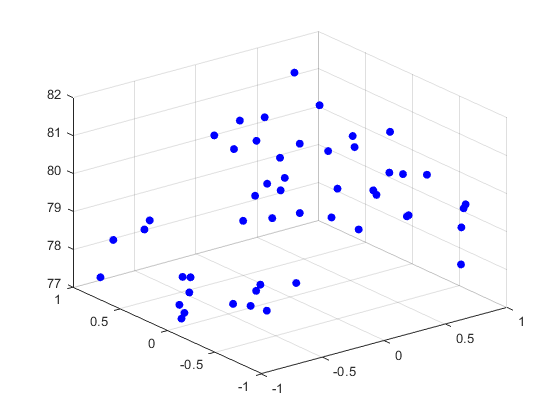

scatter3(x1, x2, y, 'blue', 'filled');

regr_1 = regstats(y, [x1, x2], 'linear', 'all');
regr_1.beta;
regr_1.rsquare;

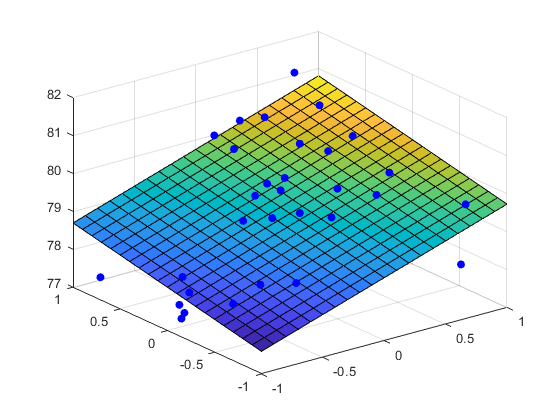

scatter3(x1, x2, y, 'blue', 'filled');
hold on;
[x_grid1, x_grid2]=meshgrid(-1:0.1:1,-1:0.1:1);
beta1 = regr_1.beta;
y1=beta1(1)+beta1(2)*x_grid1+beta1(3)*x_grid2;
surf(x_grid1, x_grid2, y1);
hold off

x11 = x1.*x1;
x22 = x2.*x2;
x12 = x1.*x2;
regr_2 = regstats(y, [x1, x2, x11, x22, x12], 'linear', 'all');
regr_2.beta

ans =    79.8225
    1.0675
    0.4161
   -1.1999
   -0.4545
    0.7493


regr_2.rsquare

ans = 0.7489

% r_1 = regr_1.r;
% r_2 = regr_2.r;
% SSE_1 = sum(r_1.^2);
% SSE_2 = sum(r_2.^2);
% 
% n = length(x1);
% k = 2;
% p = 3;
% TS = ((SSE_1 - SSE_2)/3)/(SSE_2/(n-k-p-1))

X = [];
X(:,1) = ones(50,1);
X(:,2) = x1;
X(:,3) = x2;
X(:,4) = x11;
X(:,5) = x22;
X(:,6) = x12;
H = inv(X'*X)

H =     0.0826   -0.0094    0.0023   -0.0931   -0.0940   -0.0395
   -0.0094    0.0527    0.0022    0.0154    0.0071    0.0233
    0.0023    0.0022    0.0920    0.0311   -0.0622   -0.0169
   -0.0931    0.0154    0.0311    0.2171    0.0191    0.0422
   -0.0940    0.0071   -0.0622    0.0191    0.3271    0.0899
   -0.0395    0.0233   -0.0169    0.0422    0.0899    0.2413


n = 50;
k = 5;
t = 2.0154

t = 2.0154

SSE = regr_2.fstat.sse;
S = sqrt(SSE/(n-k-1));

% Testing X_1 squared
regr_2.beta(4); 
TS_1 = regr_2.beta(4)/(S*sqrt(H(4,4)))

TS_1 = -4.7422

% Testing X_2 squared
regr_2.beta(5);
TS_2 = regr_2.beta(5)/(S*sqrt(H(5,5)))

TS_2 = -1.4631

%Testing X_3 squared
regr_2.beta(6);
TS_3 = regr_2.beta(6)/(S*sqrt(H(6,6)))

TS_3 = 2.8082